%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% alinea (d)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% (ii)

% definicao das funcoes para o runge kunta em (a)(i)
q = @(x) -1;
r = @(x) x;



% funcoes iteracao runge kutta para o z e o w
Fz = @(t, x, y) [y; -q(t).*x + r(t)];
Fw = @(t, x, y) [y; -q(t).*x];



% solucao exata da edo em (a)(i)
sol_y = @(x) (exp(1).^(1+x)+x-x*exp(1).^2-exp(1).^(1-x))./(exp(1).^2-1);



% obtencao dos z's e w's para o passo h1
h1=0.2./(2.^3);
[z1, dzdx] = rungekutta(h1, 0, 0, Fz, 1);
[w1, dwdx] = rungekutta(h1, 0, 1, Fw, 1);

% obtencao dos z's e w's para o passo h2
h2=0.1./(2.^3);
[z2, dzdx] = rungekutta(h2, 0, 0, Fz, 1);
[w2, dwdx] = rungekutta(h2, 0, 1, Fw, 1);

% calculo da solucao numerica final
y1 = z1 - z1(end)./w1(end).*w1;
y2 = z2 - z2(end)./w2(end).*w2;



% lista de x's com passo h1 e h2
x1 = 0:h1:1;
x2 = 0:h2:1;

% ponto onde vamos avaliar o erro absoluto
x = 0.5;

% para calcular a ordem de convergencia, os n's sao os indices
% na lista de cada um dos y's para os quais têm o ponto x 
% correspondente
n1 = round(x./h1)+1;
n2 = (x./h2)+1;

% erros absolutos
eh1 = abs(sol_y(x) - y1(n1));
eh2 = abs(sol_y(x) - y2(n2));


% ordem de convergência
p = log(eh1./eh2)./log(h1./h2)

p =    2.993513704361790


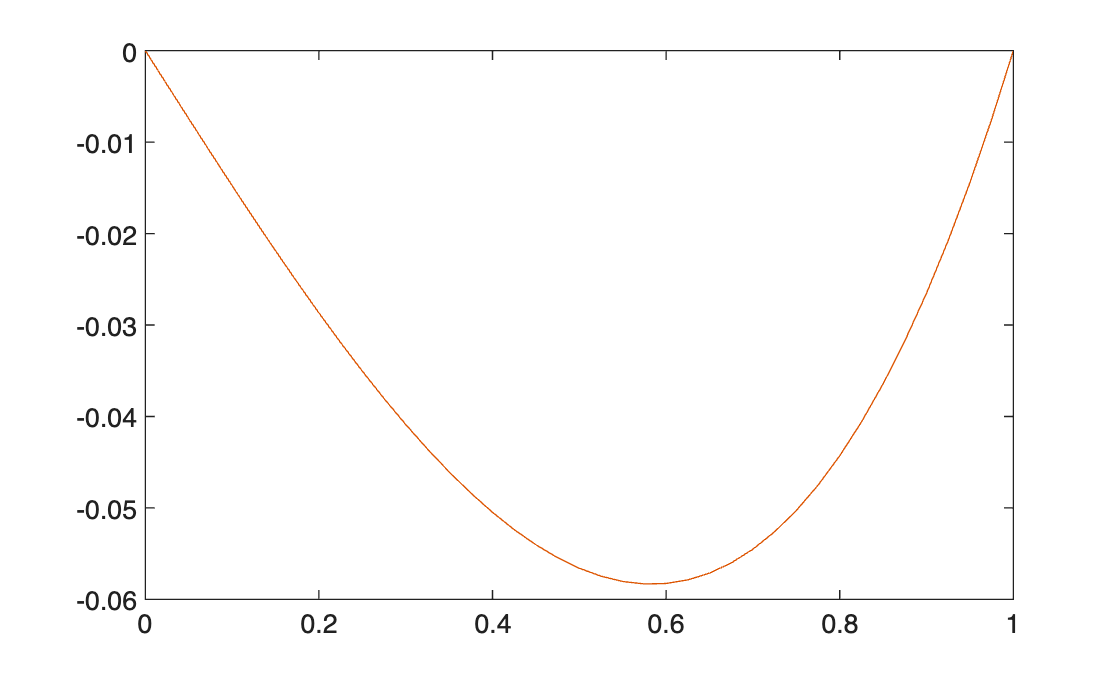


plot(x1,y1,x1,sol_y(x1))

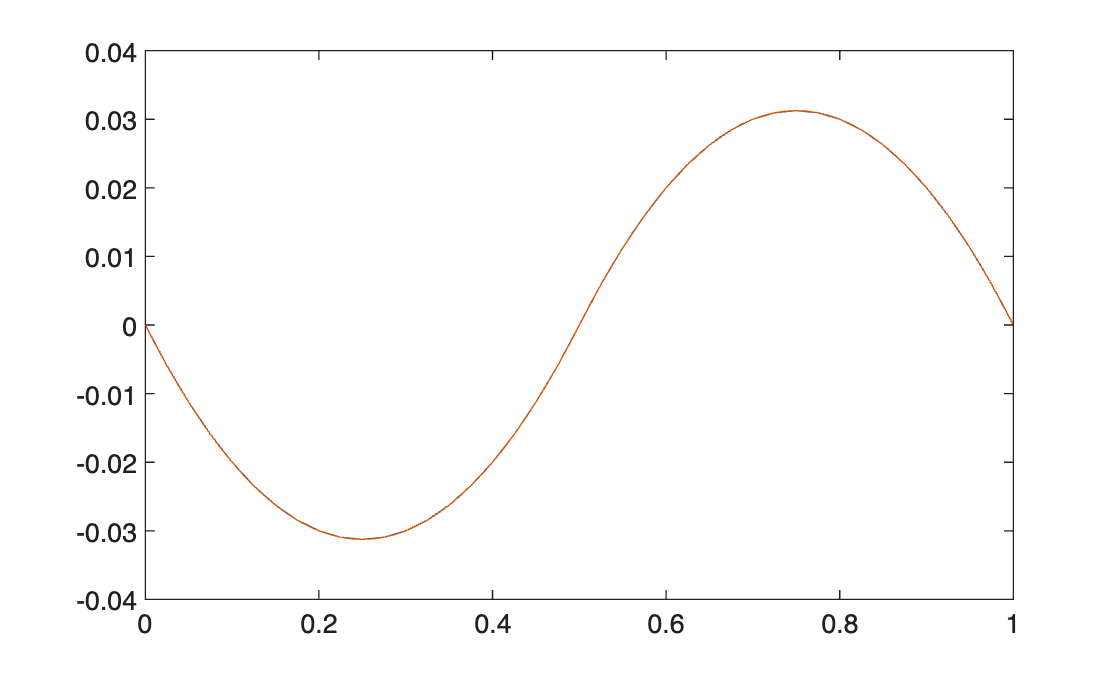


% definicao das funcoes para o runge kunta em (a)(i)
q = @(x) 0;
r = @(x) (x <= 1./2) .* 1 + (1./2 < x) .* -1;

% funcoes iteracao runge kutta para o z e o w
Fz = @(t, x, y) [y; -q(t).*x + r(t)];
Fw = @(t, x, y) [y; -q(t).*x];



% solucao exata da edo em (a)(ii)
sol_y = @(x) (x <= 0.5) .* (0.5.*x.^2 - 0.25.*x) + (0.5 < x) .* (-0.5.*(x-1).^2 - 0.25.*(x-1));



% obtencao dos z's e w's para o passo h1
%h1=0.2./(2.^10);
h1= 0.025;
[z1, dzdx] = rungekutta(h1, 0, 0, Fz, 1);
[w1, dwdx] = rungekutta(h1, 0, 1, Fw, 1);

% obtencao dos z's e w's para o passo h2
h2=0.1./(2.^3);
[z2, dzdx] = rungekutta(h2, 0, 0, Fz, 1);
[w2, dwdx] = rungekutta(h2, 0, 1, Fw, 1);


% calculo da solucao numerica final
y1 = z1 - z1(end)./w1(end).*w1;
y2 = z2 - z2(end)./w2(end).*w2;



% lista de x's com passo h1 e h2
x1 = 0:h1:1;
x2 = 0:h2:1;



plot(x1,y1, x2, sol_y(x2))

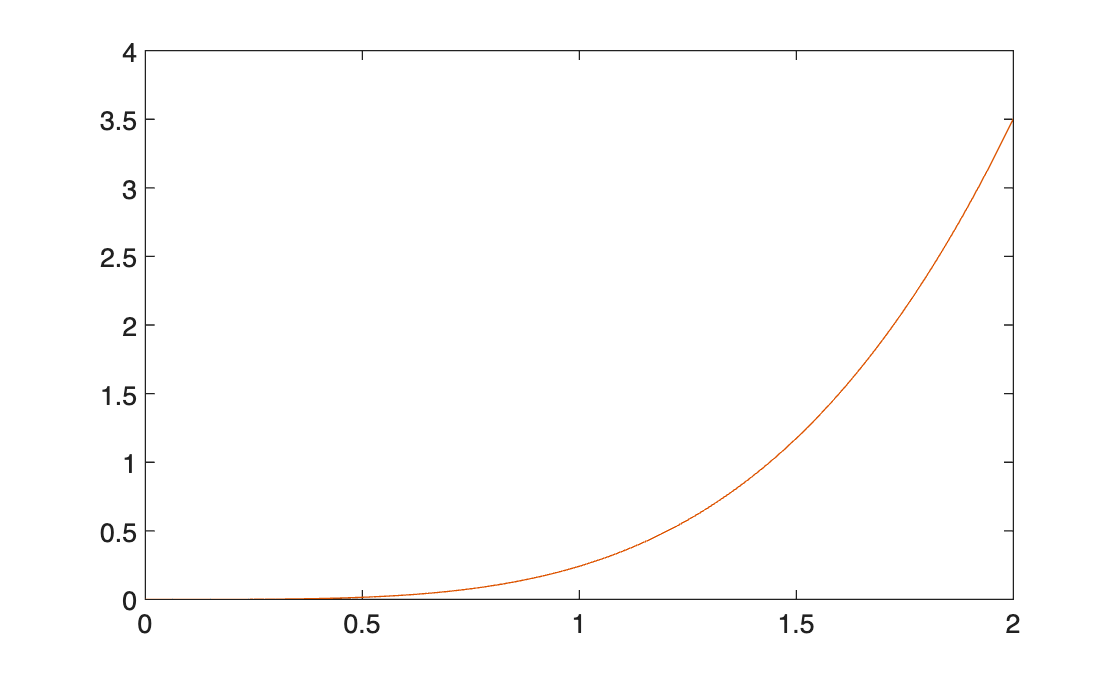

% (iii)


% funcoes do problema (8)
q = @(x) 1;
r = @(x) 3*x.^2;


% funcoes iteracao runge kutta para o z e o w
Fz = @(t, x, y) [y; -q(t).*x + r(t)];
Fw = @(t, x, y) [y; -q(t).*x];



% solucao exata da edo do problema (8)
sol_y = @(x) 6*cos(x) + 3*(x.^2 - 2);


% obtencao dos z's e w's para o passo h1
h1= 0.05;
[z1, dzdx] = rungekutta(h1, 0, 0, Fz, 2);
[w1, dwdx] = rungekutta(h1, 0, 1, Fw, 2);

% obtencao dos z's e w's para o passo h2
h2=0.1./(2.^3);
[z2, dzdx] = rungekutta(h2, 0, 0, Fz, 2);
[w2, dwdx] = rungekutta(h2, 0, 1, Fw, 2);


% condicao de fronteira
l = 6 + 6*cos(2);

% calculo da solucao numerica final
y1 = z1 + (l - z1(end))./w1(end).*w1;
y2 = z2 + (l - z2(end))./w2(end).*w2;



% lista de x's com passo h1 e h2
x1 = 0:h1:2;
x2 = 0:h2:2;


plot(x2,y2, x2, sol_y(x2))